% Olin Pump Calibration
pressures = [0 5 10 15 20 25 30 35 40 45 50 60 65 70 80];
lengths = [44.3 43.4 42.2 41.5 40.0 38.7 37.8 37.1 36.4 36.2 35.8 35.3 34.9 34.7 34.3] / 100;

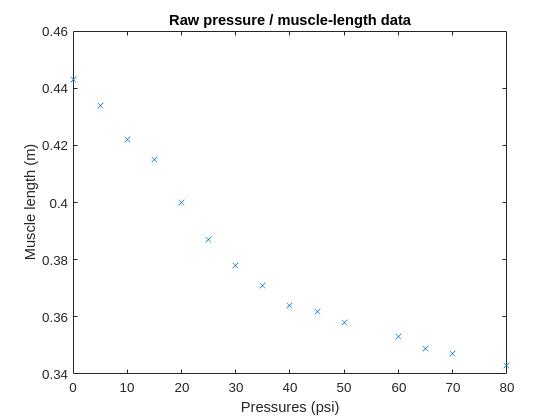

figure()
plot(pressures, lengths, 'x')
title("Raw pressure / muscle-length data")
xlabel("Pressures (psi)")
ylabel("Muscle length (m)")

## Exponential Fit

% Fit:
fit_obj = fittype("l_max + a*exp(-b*x)")

fit_obj =      General model:
     fit_obj(a,b,l_max,x) = l_max + a*exp(-b*x)

fit_results = fit(pressures(:), lengths(:), fit_obj) % Start point is optional

fit_results =      General model:
     fit_results(x) = l_max + a*exp(-b*x)
     Coefficients (with 95% confidence bounds):
       a =      0.1197  (0.1096, 0.1299)
       b =     0.02749  (0.02127, 0.03372)
       l_max =      0.3284  (0.317, 0.3398)

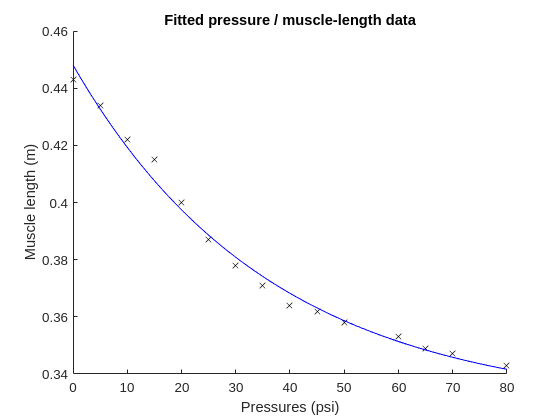

figure()
hold on
plot(pressures, lengths, 'kx')

t_pressures = linspace(pressures(1), pressures(end));
plot(t_pressures, fit_results(t_pressures), 'b');

title("Fitted pressure / muscle-length data")
xlabel("Pressures (psi)")
ylabel("Muscle length (m)")


% Create symbolic expression for the fit
syms p
sym_fit = fit_results.l_max + fit_results.a * exp(-fit_results.b * p);

% Save the symbolic expression as a Matlab function file in the
% include/utils directory
matlabFunction(sym_fit, "File", "include/utils/contraction_fit");

## Polynomial Fit

poly_fit_results = fit(pressures(:), lengths(:), 'poly5')

poly_fit_results =      Linear model Poly5:
     poly_fit_results(x) = p1*x^5 + p2*x^4 + p3*x^3 + p4*x^2 + p5*x + p6
     Coefficients (with 95% confidence bounds):
       p1 =   2.402e-10  (3.681e-11, 4.436e-10)
       p2 =  -5.593e-08  (-9.665e-08, -1.521e-08)
       p3 =   4.567e-06  (1.679e-06, 7.456e-06)
       p4 =  -0.0001352  (-0.0002216, -4.875e-05)
       p5 =  -0.0008617  (-0.001864, 0.0001405)
       p6 =      0.4422  (0.4388, 0.4457)

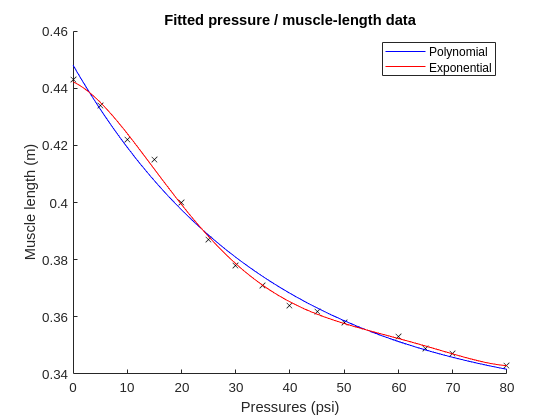

plot(t_pressures, poly_fit_results(t_pressures), 'r');
legend(["", "Polynomial", "Exponential"])

coeffs = [poly_fit_results.p1, poly_fit_results.p2, poly_fit_results.p3, poly_fit_results.p4, poly_fit_results.p5, poly_fit_results.p6];
sym_poly_fit = coeffs * [p^5, p^4, p^3, p^2, p^1, 1]';
matlabFunction(sym_poly_fit, "File", "include/utils/contraction_fit_poly");

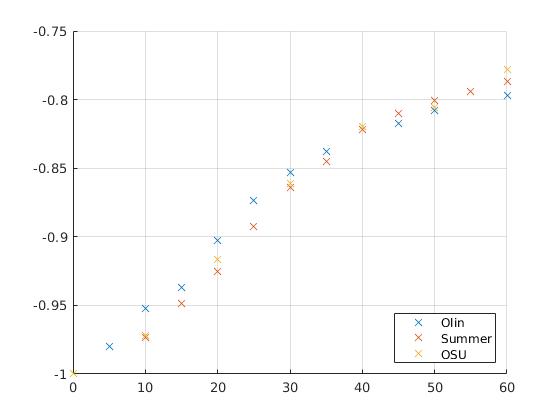

%pressures_summer = [0 10 15 20 25 30 35 40 45 50 55 60 65 70 80];
%lengths_summer = [42.4 41.8 40.7 39.8 38.5 37.3 36.6 35.7 35 34.7 34.4 34 33.65 33.3 32.8];
pressures_summer = [0 10 15 20 25 30 35 40 45 50 55 60];
lengths_summer = [42.7 41.55 40.5 39.5 38.1 36.9 36.1 35.1 34.6 34.2 33.9 33.6] / 100;

pressures_osu = [0 10 20 30 40 50 60];
lengths_osu = [36 35 33 31 29.5 29.0 28.0];
strains_osu = lengths_osu / lengths_osu(1);

strains_summer = lengths_summer / lengths_summer(1);
strains_olin = lengths / lengths(1);

figure()
hold on
plot(pressures(1:end-3), -strains_olin(1:end-3), 'x')
plot(pressures_summer, -strains_summer, 'x')
plot(pressures_osu, -strains_osu, 'x')
legend("Olin", "Summer", "OSU", location="southeast")
grid on

poly_fit_results_summer = fit(pressures_summer(:), lengths_summer(:), 'poly5')

poly_fit_results_summer =      Linear model Poly5:
     poly_fit_results_summer(x) = p1*x^5 + p2*x^4 + p3*x^3 + p4*x^2 + p5*x + p6
     Coefficients (with 95% confidence bounds):
       p1 =  -3.003e-10  (-9.187e-10, 3.182e-10)
       p2 =   2.667e-08  (-6.797e-08, 1.213e-07)
       p3 =   5.394e-07  (-4.611e-06, 5.69e-06)
       p4 =  -8.216e-05  (-0.0001997, 3.536e-05)
       p5 =  -0.0003982  (-0.001382, 0.0005852)
       p6 =       0.427  (0.4247, 0.4292)

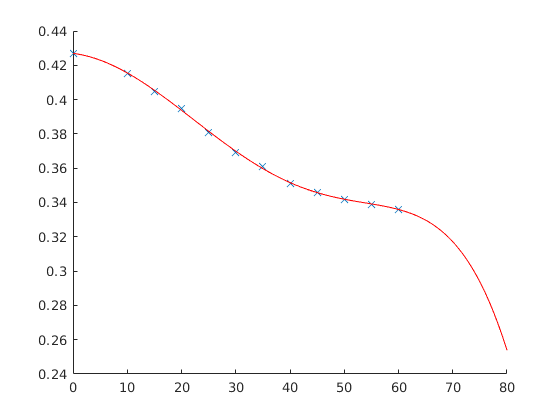

figure()
hold on
plot(pressures_summer, lengths_summer, 'x')
plot(t_pressures, poly_fit_results_summer(t_pressures), 'r');

coeffs = [poly_fit_results_summer.p1, poly_fit_results_summer.p2, poly_fit_results_summer.p3, poly_fit_results_summer.p4, poly_fit_results_summer.p5, poly_fit_results_summer.p6];
sym_poly_fit = coeffs * [p^5, p^4, p^3, p^2, p^1, 1]';
matlabFunction(sym_poly_fit, "File", "include/utils/contraction_fit_summer");